# Neural Networks

The concept is simple, think about a simple method of deciding a computer can take a decision, some smart people find the following solution: 


$$\textrm{Output}=\textrm{x1}*\textrm{w1}+\textrm{x2}*\textrm{w2}+b\;$$



$$\textrm{Where}:$$


- 
$$\textrm{x1}\;\textrm{and}\;\textrm{x2}\;\textrm{means}:\textrm{How}\;\textrm{much}\;i\;\textrm{want}\;\textrm{to}\;\textrm{do}\;\textrm{this}\;\textrm{"activity"}?$$


- 
$$\textrm{w1}\;\textrm{and}\;\textrm{w2}\;\textrm{means}:\textrm{What}\;\textrm{benefits}\;\textrm{am}\;i\;\textrm{going}\;\textrm{to}\;\textrm{get}\;\textrm{for}\;\textrm{doing}\;\textrm{those}\;\textrm{activities}?$$


- 
$$b\;\textrm{means}:\textrm{What}\;\textrm{is}\;\textrm{my}\;\textrm{mood}\;\textrm{right}\;\textrm{now}?$$


- If the output is over 1 i will do it otherwise i don't

Obviously /ˈɒb.vi.əs.li/, you can add as many activities as you want (x). So, suppose you fell in love with a girl, now i am going to to help you to decide if stay or leave the country. Let's sum up the situation: 

- x1: How much do i want to want i baby right now? I mean, I am not really excited "0.3"

- x2: Do I love this girl? Yes and i don want her to carry on a baby alone so: 0.9

- w1: How good is having a baby? the stress and money point out to a fair: -0.15

- w2: The girl value as a partner? all womans are crazy but this one is my entire world so: 1 (I suppose you love her)

- b: Today i had a really beautiful day, i am doing well in my job so a fair 0.7


$$\mathrm{Output}=0\ldotp 3*-0\ldotp 15+0\ldotp 9*1+0\ldotp 7=1\ldotp 555$$


It seems like you are gonna be a father. Supposing you are neutral and your mood do not affect your decision, so, you will stay with her yet. But if you were not in love, probably the baby would have been like one of the many children in Latin America (I am a Latino).


$$\begin{array}{l}
\mathrm{step}\left(z\right)=\left\lbrace \begin{array}{ll}
0 & ,\mathrm{if}\;z<0\\
1 & ,\mathrm{if}\;z\ge 0
\end{array}\right.\\
\sigma \left(z\right)=\frac{1}{1+e^{-z} }
\end{array}$$


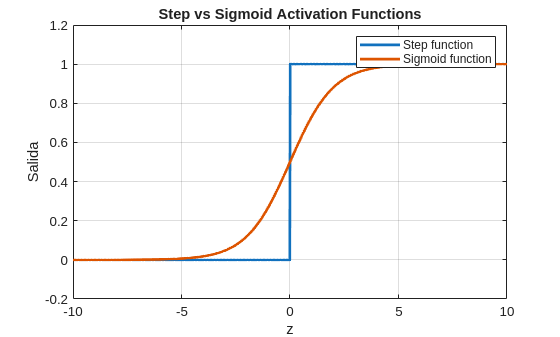

% Rango de valores
z = linspace(-10, 10, 1000);

% Funcion step (Heaviside)
step = double(z >= 0);

% Funcion sigmoide
sigmoid = 1 ./ (1 + exp(-z));

% Grafica
figure;
plot(z, step, 'LineWidth', 2);
hold on;
plot(z, sigmoid, 'LineWidth', 2);
hold off;

% Ajuste del eje y
ylim([-0.2 1.2]);

% Etiquetas y leyenda
xlabel('z');
ylabel('Salida');
legend('Step function', 'Sigmoid function');
title('Step vs Sigmoid Activation Functions');
grid on;

Why using the sigmoid function instead of just the step function? Because later we will have to minimze w and b, for that we have to calculate the gradient descent algorithm that consist on finding partial derivatives and the step function is not derivative, but the sigmoid function yes.